clc; clear all; close all;

% test cell

filename = 'finaltestvectors\finaltest1';

% % (filename, wr=1 to write)
% APT_demodulate(filename, 0)

% modulator(filename)
impairment(filename, 2)

load("sync_a.mat");

% Extract audio data 
%filename = 'Test_Files\demodtest3.wav';
filename = 'finaltestvectors\finaltest3.wav';

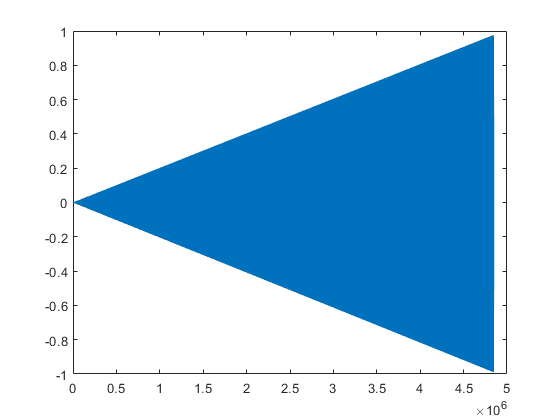


[y,fs] = audioread(filename);
figure()
plot(y)

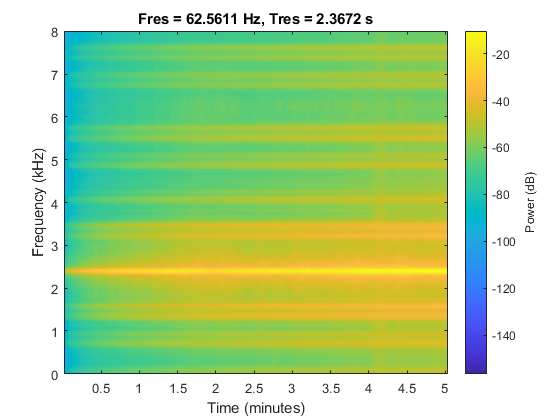


pspectrum(y, fs,"spectrogram")

% zq = pamdemod(yrs,8);
% x = zq .* ct';
% % filter
% x_lpf = lowpass(x,fc, resamp_fs);
% pspectrum(x_lpf, resamp_fs,"spectrogram")
% plot (x_lpf)

% Extract audio data 
% -> Resample by 16640/16000 
% -> get carrier wave 
% -> multiply 
% -> filter 

% -> downsample 
% -> correlation

%fs = 16e3; % 16kHz
Ts = 1/fs;
input_bit_res = 16; % 16 bit

output_bit_res = 8;
% 1818 by n lines
width = 1818;
%height = n;
samples_per_line = 8000;
frs = 16640; % 16.640kHz
Trs = 1/frs;

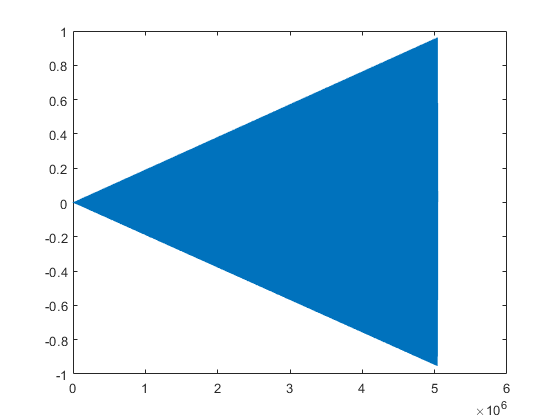

% -> Resample by 16640/16000

l = length(y);

desired_ratio = 16640/16000;
step_per_sample = 1/desired_ratio;
x = 1:l;
xq = 0:step_per_sample:l-step_per_sample;
yrs = interp1(x,y,xq);

yrs = yrs(3:end);% get rid of NaNs
% total_wanted_samples = 8000 * total_lines;
% 8320
% x = 0:(size(result_image,2) - 1);
% xq = 0:(total_wanted_samples-1);  
% 
% yrs = interp1(x,result_image,xq);

plot(yrs)

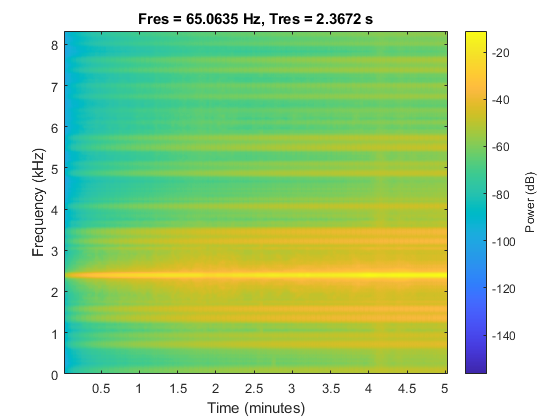

pspectrum(yrs, frs,"spectrogram")

% APT transmits images using pulse amplitude modulation (PAM) of a 2.4 kHz carrier.
% -> get carrier wave
fc = 2400; % 2.4kHz carrier freq
samples = length(yrs);
Ac = 1; % Carrier wave magnitude
t = 0:Trs:samples/frs; % 0.5 seconds
ct = Ac * cos(2*pi*fc*t); % c(t) => carrier wave


filterOrder = 7;
fcutoff = 3500;
[b,a]=butter(filterOrder,fcutoff/(fs/2));


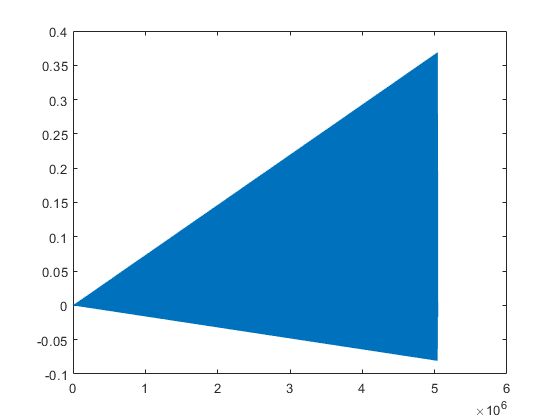


% multiply by carrier
yrs_mult_ct = yrs .* ct(2:end);
% filter
y_dm_lpf = filtfilt(b,a,yrs_mult_ct);
% yrs_mult_ct_LPF = lowpass(yrs_mult_ct,fc, frs);

plot(y_dm_lpf)

%pspectrum(y_dm_lpf, frs,"spectrogram")

% de PAM the thing

% upsample sync_a by 4
sync_a_sample_count = length(sync_a);
desired_ratio = 4;
step_per_sample = 1/desired_ratio;
xsync = 1:sync_a_sample_count;
xqsync = 0:step_per_sample:sync_a_sample_count-step_per_sample;
sync_a_upsampled_4x = interp1(xsync,sync_a,xqsync);

% ->normalize
y_norm = y_dm_lpf / max(abs(y_dm_lpf));
% ->correlate
[z,lag_z] = xcorr(sync_a_upsampled_4x, y_norm(1:8400));
z = z/max(z);
%plot(z)

% calculating lag and aligning signal
[Mz,Iz] = max(z); % calculate index of the correlation peak
tz = lag_z(Iz); % find offset value
if (tz < 0)
    tz_abs = -tz;
else 
    tz_abs = tz;
end
%zc = y_norm(tz_abs:end);

zc = circshift(y_norm,tz_abs); % align signal

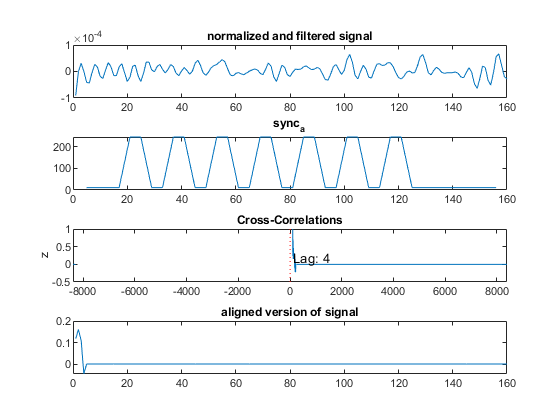


subplot(4,1,1)
plot(y_norm(1:160))
title('normalized and filtered signal')

subplot(4,1,2)
plot(sync_a_upsampled_4x)
title('sync_a')

subplot(4,1,3)
plot(lag_z,circshift(z,100),[tz tz],[-0.5 1],'r:');
text(tz+100,0.2,['Lag: ' int2str(tz)])
ylabel('z')
axis tight
title('Cross-Correlations')


subplot(4,1,4)
plot(zc(1:160))
title('aligned version of signal') % supposed to be
hold off

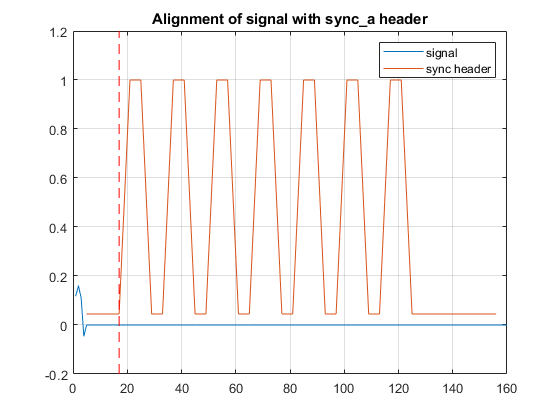

figure()
plot(zc(1:160))
hold on
plot(1:length(sync_a_upsampled_4x),...
    sync_a_upsampled_4x/max(abs(sync_a_upsampled_4x)), [17 17],[-.2 1.2],'r--')
title('Alignment of signal with sync\_a header')
legend('signal', 'sync header')
grid();
hold off

samples_per_line_2 = 8320; % samples/line for upsampled signal
% space_a = zeros([1 47]);
% iterate through signal to recreate array
total_samples = length(zc);
h = int16(total_samples/samples_per_line_2);
apt_array = zeros(h,samples_per_line_2);
line_sample = 1;


% l = length(zc);
% 
% desired_ratio = 16000/16640;
% step_per_sample = 1/desired_ratio;
% x = 1:l;
% xq = 0:step_per_sample:l-step_per_sample;
% zcrs = interp1(x,zc,xq);
total_samples = length(zc);
%zc = zc(3:end);

row = 1;
for i = 1:samples_per_line_2:total_samples
        if i < total_samples-samples_per_line_2
            current_slice = zc(i:i+samples_per_line_2-1);
            current_slice_rescaled = (rescale(current_slice,11,244));
            apt_array(row, :) = int16(current_slice_rescaled);
            row = row+1;
        else 
            apt_array(row,1:length(zc(i:end))) = zc(i:end);
        end
end

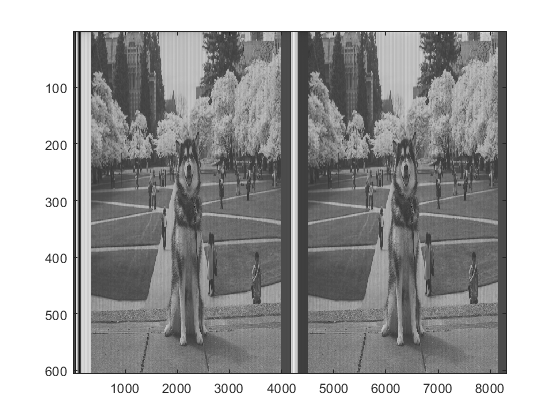

figure()
imagesc(apt_array);
 colormap("gray");

% resize and write image to file

word = 4;
filewrite = 'finaltestvectors\Side_a_Doggo.jpeg'

filewrite = 'finaltestvectors\Side_a_Doggo.jpeg'

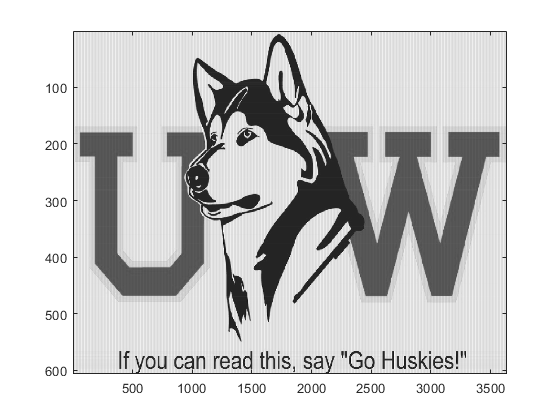

map =  colormap("gray"); 

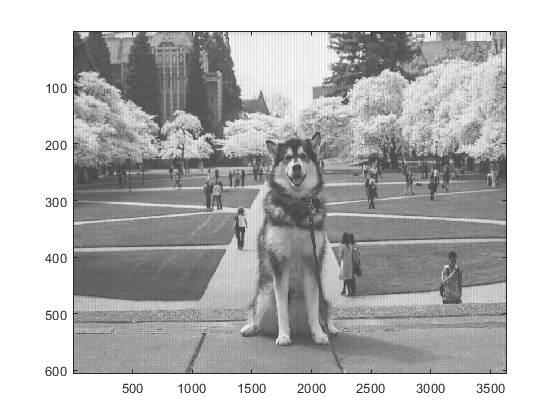

imagesc(apt_array(:,87*word:996*word));

image = imresize(apt_array(:,87*word:996*word),[1101 909]);
imwrite(image,map,filewrite);
% figure()



% imagesc(apt_array); 

